clearvars; clc;

# Esercitazione 5

#### Definitions

A=[0.3 1.5;0.5 -0.4];
B=[0;1];

n=2;

x_k=[20;20];

#### Finite horizon quadratic optimal control - Problem 1

Q=diag([20 5]);
R=5;
Hp=3;

A_cal=[A;A^2;A^3];
B_cal=[B zeros(n,1) zeros(n,1);A*B B zeros(n,1);A^2*B A*B B];
Q_cal=blkdiag(Q,Q,Q); % Hp=3 -> Q_cal=blkdiag(Q,Q,S) but S=Q
R_cal=blkdiag(R,R,R);

H=2*(B_cal'*Q_cal*B_cal+R_cal);
F=2*A_cal'*Q_cal*B_cal;
J=x_k'*A_cal'*Q_cal*A_cal*x_k;

u_k=-H\F'*x_k

u_k =    -7.5261
  -18.7716
   -0.3400


X_k=A_cal*x_k+B_cal*u_k

X_k =    36.0000
   -5.5261
    2.5109
    1.4388
    2.9115
    0.3400


#### Saturation - Problem 2

-13 <= u(k|k) <= 13

-13 <= u(k+1|k) <= 13

-13 <= u(k+2|k) <= 13


$$\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\left(k|k\right)\\
u\left(k+1|k\right)\\
u\left(k+2|k\right)
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
13\\
13\\
13
\end{array}\right\rbrack$$
               
$$-\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\left(k|k\right)\\
u\left(k+1|k\right)\\
u\left(k+2|k\right)
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
13\\
13\\
13
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
I_3 \\
-I_3 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\left(k|k\right)\\
u\left(k+1|k\right)\\
u\left(k+2|k\right)
\end{array}\right\rbrack \le \left\lbrack \begin{array}{c}
13\\
13\\
13
\end{array}\right\rbrack \to \mathrm{GU}\left(k|k\right)\le h$$


G=[eye(3);-eye(3)];
h=13*ones(6,1);
H=(H+H')/2; %verifica che H sia simmetrica
U=quadprog(H,x_k'*F,G,h);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



X_k1=A_cal*x_k+B_cal*U

X_k1 =    36.0000
   -4.7928
    3.6109
    6.9171
   11.4589
   -0.4807


#### Receding Horizon - Problem 3

x_traj(1,:)=x_k; %initial state

%RH 20 steps
for kk=1:20
    U=quadprog(H,x_k'*F,G,h)
    x_traj(kk+1,:)=A*x_k+B*U(1);
    u_traj(kk)=U(1);
    x_k=x_traj(kk+1,:)';
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.7928
  -13.0000
    0.4807



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =   -13.0000
   -0.8835
   -3.2337



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.9369
   -5.9937
   -0.0485



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -6.0163
   -0.2324
   -0.2467



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.2371
   -0.4612
   -0.0105



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.4630
   -0.0304
   -0.0190



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.0308
   -0.0358
   -0.0013



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.0360
   -0.0033
   -0.0015



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.0033
   -0.0028
   -0.0001



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U =    -0.0028
   -0.0003
   -0.0001



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-03 *

   -0.3303
   -0.2222
   -0.0139



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-03 *

   -0.2233
   -0.0310
   -0.0092



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-04 *

   -0.3123
   -0.1772
   -0.0131



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-04 *

   -0.1780
   -0.0284
   -0.0073



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-05 *

   -0.2861
   -0.1423
   -0.0120



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-05 *

   -0.1430
   -0.0255
   -0.0059



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-06 *

   -0.2565
   -0.1150
   -0.0107



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-06 *

   -0.1156
   -0.0225
   -0.0048



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-07 *

   -0.2265
   -0.0934
   -0.0094



Solver stalled, constraints satisfied.
quadprog stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


U = 1.0e-08 *

   -0.9393
   -0.1965
   -0.0388


#### Plot

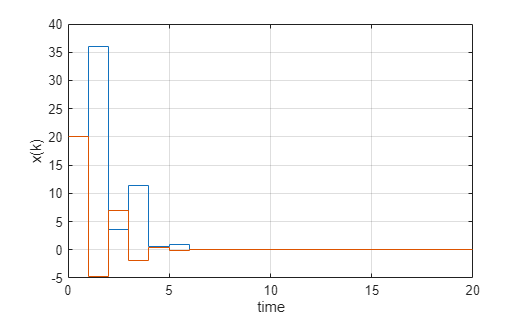

figure, stairs((0:1:20),x_traj), grid on, xlabel('time'), ylabel('x(k)');

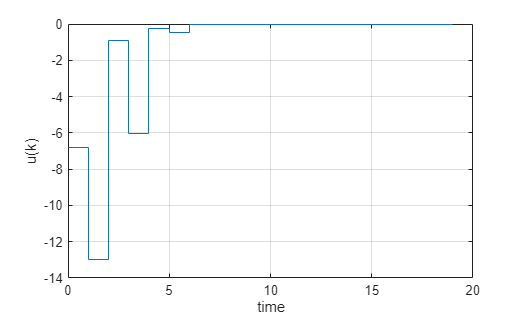

figure, stairs((0:1:19),u_traj), grid on, xlabel('time'), ylabel('u(k)');